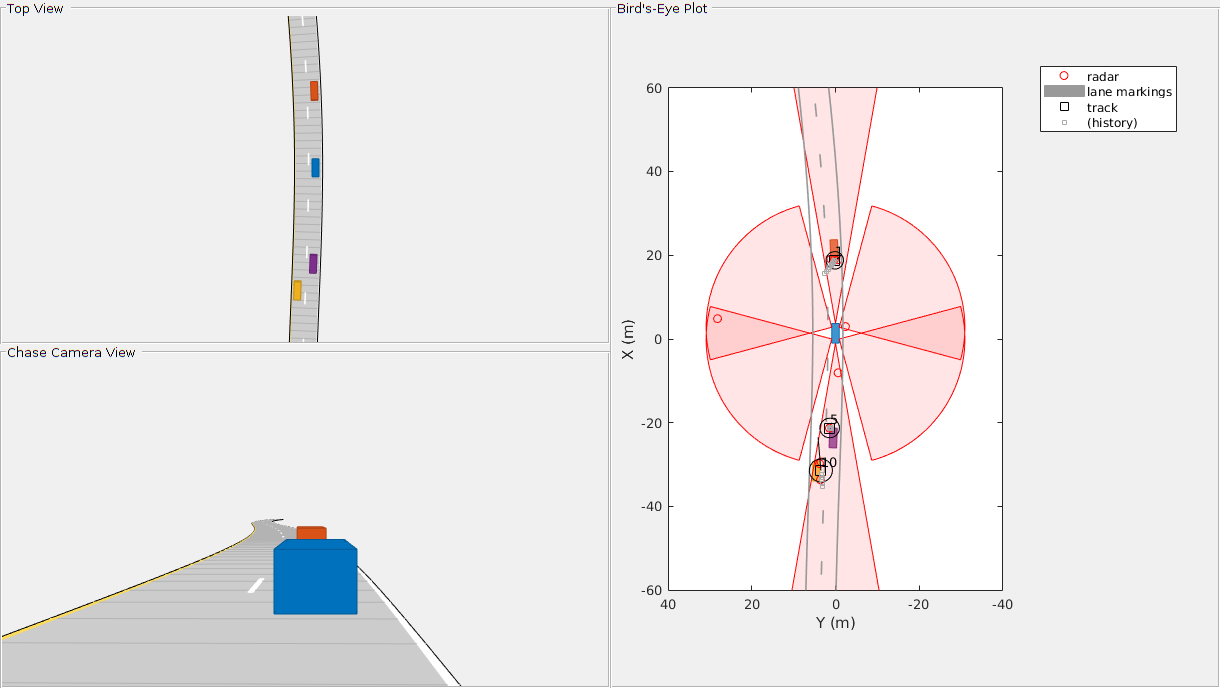

%% Sensor Fusion Using Synthetic Radar

%% Generate the Scenario
% Scenario generation comprises generating a road network, defining
% vehicles that move on the roads, and moving the vehicles.
% 
% Test the ability of the sensor fusion to track a
% vehicle that is passing on the left of the ego vehicle. The scenario
% simulates a highway setting, and additional vehicles are in front of and
% behind the ego vehicle.

% Define an empty scenario.
scenario = drivingScenario;
scenario.SampleTime = 0.01;

%% 
% Add a stretch of 500 meters of typical highway road with two lanes. The 
% road is defined using a set of points, where each point defines the center of 
% the road in 3-D space. 
roadCenters = [0 0; 50 0; 100 0; 250 20; 500 40];
road(scenario, roadCenters, 'lanes',lanespec(2));

%% 
% Create the ego vehicle and three cars around it: one that overtakes the
% ego vehicle and passes it on the left, one that drives right in front of
% the ego vehicle and one that drives right behind the ego vehicle. All the
% cars follow the trajectory defined by the road waypoints by using the
% |trajectory| driving policy. The passing car will start on the right
% lane, move to the left lane to pass, and return to the right lane.

% Create the ego vehicle that travels at 25 m/s along the road.  Place the
% vehicle on the right lane by subtracting off half a lane width (1.8 m)
% from the centerline of the road.
egoCar = vehicle(scenario, 'ClassID', 1);
trajectory(egoCar, roadCenters(2:end,:) - [0 1.8], 25); % On right lane

% Add a car in front of the ego vehicle
leadCar = vehicle(scenario, 'ClassID', 1);
trajectory(leadCar, [70 0; roadCenters(3:end,:)] - [0 1.8], 25); % On right lane

% Add a car that travels at 35 m/s along the road and passes the ego vehicle
passingCar = vehicle(scenario, 'ClassID', 1);
waypoints = [0 -1.8; 50 1.8; 100 1.8; 250 21.8; 400 32.2; 500 38.2];
trajectory(passingCar, waypoints, 35);

% Add a car behind the ego vehicle
chaseCar = vehicle(scenario, 'ClassID', 1);
trajectory(chaseCar, [25 0; roadCenters(2:end,:)] - [0 1.8], 25); % On right lane

%% Define Radar Sensors
% Simulate an ego vehicle that has 6 radar sensors and
% The ego vehicle is equipped with a
% long-range radar sensor. Each side of the vehicle has two short-range radar
% sensors, each covering 90 degrees. One sensor on each side covers from
% the middle of the vehicle to the back. The other sensor on each side
% covers from the middle of the vehicle forward. The figure in the next
% section shows the coverage.

sensors = cell(6,1);
% Front-facing long-range radar sensor at the center of the front bumper of the car.
sensors{1} = radarDetectionGenerator('SensorIndex', 1, 'Height', 0.2, 'MaxRange', 174, ... 
    'SensorLocation', [egoCar.Wheelbase + egoCar.FrontOverhang, 0], 'FieldOfView', [20, 5]);

% Rear-facing long-range radar sensor at the center of the rear bumper of the car.
sensors{2} = radarDetectionGenerator('SensorIndex', 2, 'Height', 0.2, 'Yaw', 180, ...
    'SensorLocation', [-egoCar.RearOverhang, 0], 'MaxRange', 174, 'FieldOfView', [20, 5]);

% Rear-left-facing short-range radar sensor at the left rear wheel well of the car.
sensors{3} = radarDetectionGenerator('SensorIndex', 3, 'Height', 0.2, 'Yaw', 120, ...
    'SensorLocation', [0, egoCar.Width/2], 'MaxRange', 30, 'ReferenceRange', 50, ...
    'FieldOfView', [90, 5], 'AzimuthResolution', 10, 'RangeResolution', 1.25);

% Rear-right-facing short-range radar sensor at the right rear wheel well of the car.
sensors{4} = radarDetectionGenerator('SensorIndex', 4, 'Height', 0.2, 'Yaw', -120, ...
    'SensorLocation', [0, -egoCar.Width/2], 'MaxRange', 30, 'ReferenceRange', 50, ...
    'FieldOfView', [90, 5], 'AzimuthResolution', 10, 'RangeResolution', 1.25);

% Front-left-facing short-range radar sensor at the left front wheel well of the car.
sensors{5} = radarDetectionGenerator('SensorIndex', 5, 'Height', 0.2, 'Yaw', 60, ...
    'SensorLocation', [egoCar.Wheelbase, egoCar.Width/2], 'MaxRange', 30, ...
    'ReferenceRange', 50, 'FieldOfView', [90, 5], 'AzimuthResolution', 10, ...
    'RangeResolution', 1.25);

% Front-right-facing short-range radar sensor at the right front wheel well of the car.
sensors{6} = radarDetectionGenerator('SensorIndex', 6, 'Height', 0.2, 'Yaw', -60, ...
    'SensorLocation', [egoCar.Wheelbase, -egoCar.Width/2], 'MaxRange', 30, ...
    'ReferenceRange', 50, 'FieldOfView', [90, 5], 'AzimuthResolution', 10, ...
    'RangeResolution', 1.25);

%% Create a Tracker
% Create a |<matlab:doc('multiObjectTracker') multiObjectTracker>| to track
% the vehicles that are close to the ego vehicle. The tracker uses the
% |initSimDemoFilter| supporting function to initialize a constant velocity
% linear Kalman filter that works with position and velocity.
% 
% Tracking is done in 2-D. Although the sensors return measurements in 3-D,
% the motion itself is confined to the horizontal plane, so there is no
% need to track the height.



%% TODO*
%Change the Tracker Parameters and explain the reasoning behind selecting
%the final values. You can find more about parameters here: https://www.mathworks.com/help/driving/ref/multiobjecttracker-system-object.html

tracker = multiObjectTracker('FilterInitializationFcn', @initSimDemoFilter, ...
    'AssignmentThreshold', 30, 'ConfirmationParameters', [4 5], 'NumCoastingUpdates', 5);
positionSelector = [1 0 0 0; 0 0 1 0]; % Position selector
velocitySelector = [0 1 0 0; 0 0 0 1]; % Velocity selector

% Create the display and return a handle to the bird's-eye plot
BEP = createDemoDisplay(egoCar, sensors);



%% Simulate the Scenario
% The following loop moves the vehicles, calls the sensor simulation, and
% performs the tracking.
% 
% Note that the scenario generation and sensor simulation can have
% different time steps. Specifying different time steps for the scenario
% and the sensors enables you to decouple the scenario simulation from the
% sensor simulation. This is useful for modeling actor motion with high
% accuracy independently from the sensor's measurement rate.
% 
% Another example is when the sensors have different update rates. Suppose
% one sensor provides updates every 20 milliseconds and another sensor
% provides updates every 50 milliseconds. You can specify the scenario with
% an update rate of 10 milliseconds and the sensors will provide their
% updates at the correct time.
% 
% In this example, the scenario generation has a time step of 0.01 second,
% while the sensors detect every 0.1 second. The sensors return a logical
% flag, |isValidTime|, that is true if the sensors generated detections.
% This flag is used to call the tracker only when there are detections.
% 
% Another important note is that the sensors can simulate multiple
% detections per target, in particular when the targets are very close to
% the radar sensors. Because the tracker assumes a single detection per
% target from each sensor, you must cluster the detections before the
% tracker processes them. This is done by the function |clusterDetections|.
% See the 'Supporting Functions' section.

toSnap = true;
while advance(scenario) && ishghandle(BEP.Parent)    
    % Get the scenario time
    time = scenario.SimulationTime;
    
    % Get the position of the other vehicle in ego vehicle coordinates
    ta = targetPoses(egoCar);
    
    % Simulate the sensors
    detections = {};
    isValidTime = false(1,6);
    for i = 1:6
        [sensorDets,numValidDets,isValidTime(i)] = sensors{i}(ta, time);
        if numValidDets
            detections = [detections; sensorDets]; %#ok<AGROW>
        end
    end
    
    % Update the tracker if there are new detections
    if any(isValidTime)
        vehicleLength = sensors{1}.ActorProfiles.Length;
        detectionClusters = clusterDetections(detections, vehicleLength);
        confirmedTracks = updateTracks(tracker, detectionClusters, time);
        
        % Update bird's-eye plot
        updateBEP(BEP, egoCar, detections, confirmedTracks, positionSelector, velocitySelector);
    end
    
    % Snap a figure for the document when the car passes the ego vehicle
    if ta(1).Position(1) > 0 && toSnap
        toSnap = false;
        snapnow
    end
end


%% Supporting Functions
%
%
% This function initializes a constant velocity filter based on a detection.

function filter = initSimDemoFilter(detection)
% Use a 2-D constant velocity model to initialize a trackingKF filter.
% The state vector is [x;vx;y;vy]
% The detection measurement vector is [x;y;vx;vy]
% As a result, the measurement model H is
H = [1 0 0 0;
     0 0 1 0;
     0 1 0 0;
     0 0 0 1;];

% Implement the Kalman filter using trackingKF function. If stuck
% review the implementation discussed in the project walkthrough
filter = trackingKF('MotionModel', '2D Constant Velocity', ...
                    'State', H' * detection.Measurement, ...
                    'MeasurementModel', H, ...
                    'StateCovariance', H' * detection.MeasurementNoise * H, ...
                    'MeasurementNoise', detection.MeasurementNoise);
end

%%%
% *|clusterDetections|*
% 
% This function merges multiple detections suspected to be of the same
% vehicle to a single detection. The function looks for detections that are
% closer than the size of a vehicle. Detections that fit this criterion are
% considered a cluster and are merged to a single detection at the centroid
% of the cluster. The measurement noises are modified to represent the
% possibility that each detection can be anywhere on the vehicle.
% Therefore, the noise should have the same size as the vehicle size.
% 
% In addition, this function removes the third dimension of the measurement 
% (the height) and reduces the measurement vector to [x;y;vx;vy].
function detectionClusters = clusterDetections(detections, vehicleSize)
N = numel(detections);
distances = zeros(N);

for i = 1:N
    for j = i+1:N
        if detections{i}.SensorIndex == detections{j}.SensorIndex
            distances(i,j) = norm(detections{i}.Measurement(1:2) - detections{j}.Measurement(1:2));
        else
            distances(i,j) = inf;
        end
    end
end

leftToCheck = 1:N;
i = 0;
detectionClusters = cell(N,1);

while ~isempty(leftToCheck)    
    % Remove the detections that are in the same cluster as the one under
    % consideration. Complete the clustering loop based on the
    % implementation discussed in the lesson.
    underConsideration = leftToCheck(1);
    clusterInds = (distances(underConsideration, leftToCheck) < vehicleSize);
    detInds = leftToCheck(clusterInds);
    clusterDets = [detections{detInds}];
    clusterMeas = [clusterDets.Measurement];
    meas = mean(clusterMeas, 2);
    meas2D = [meas(1:2);
              meas(4:5);];
    
    i = i + 1;
    detectionClusters{i} = detections{detInds(1)};
    detectionClusters{i}.Measurement = meas2D;
    leftToCheck(clusterInds) = [];
end

detectionClusters(i+1:end) = [];

% Since the detections are now for clusters, modify the noise to represent
% that they are of the whole car
for i = 1:numel(detectionClusters)
    measNoise(1:2,1:2) = vehicleSize^2 * eye(2);
    measNoise(3:4,3:4) = eye(2) * 100 * vehicleSize^2;
    detectionClusters{i}.MeasurementNoise = measNoise;
end
end

%%% 
% *|createDemoDisplay|*
% 
% This function creates a three-panel display:
% 
% # Top-left corner of display: A top view that follows the ego vehicle.
% # Bottom-left corner of display: A chase-camera view that follows the ego vehicle.
% # Right-half of display: A <matlab:doc('birdsEyePlot') bird's-eye plot> display.
function BEP = createDemoDisplay(egoCar, sensors)
    % Make a figure
    hFigure = figure('Position', [0, 0, 1200, 640], 'Name', 'Sensor Fusion with Synthetic Data Example');
    movegui(hFigure, [0 -1]); % Moves the figure to the left and a little down from the top    

    % Add a car plot that follows the ego vehicle from behind
    hCarViewPanel = uipanel(hFigure, 'Position', [0 0 0.5 0.5], 'Title', 'Chase Camera View');
    hCarPlot = axes(hCarViewPanel);
    chasePlot(egoCar, 'Parent', hCarPlot);

    % Add a car plot that follows the ego vehicle from a top view
    hTopViewPanel = uipanel(hFigure, 'Position', [0 0.5 0.5 0.5], 'Title', 'Top View');
    hCarPlot = axes(hTopViewPanel);
    chasePlot(egoCar, 'Parent', hCarPlot, 'ViewHeight', 130, 'ViewLocation', [0 0], 'ViewPitch', 90);
    
    % Add a panel for a bird's-eye plot
    hBEVPanel = uipanel(hFigure, 'Position', [0.5 0 0.5 1], 'Title', 'Bird''s-Eye Plot');
    
    % Create bird's-eye plot for the ego car and sensor coverage
    hBEVPlot = axes(hBEVPanel);
    frontBackLim = 60;
    BEP = birdsEyePlot('Parent', hBEVPlot, 'Xlimits', [-frontBackLim frontBackLim], 'Ylimits', [-35 35]);
    
    % Plot the coverage areas for radars
    for i = 1:6
        cap = coverageAreaPlotter(BEP,'FaceColor','red','EdgeColor','red');
        plotCoverageArea(cap, sensors{i}.SensorLocation,...
            sensors{i}.MaxRange, sensors{i}.Yaw, sensors{i}.FieldOfView(1));
    end
    
    % Plot the coverage areas for vision sensors
%     for i = 7:8
%         cap = coverageAreaPlotter(BEP,'FaceColor','blue','EdgeColor','blue');
%         plotCoverageArea(cap, sensors{i}.SensorLocation,...
%             sensors{i}.MaxRange, sensors{i}.Yaw, 45);
%     end
    
    % Create a vision detection plotter put it in a struct for future use
%     detectionPlotter(BEP, 'DisplayName','vision', 'MarkerEdgeColor','blue', 'Marker','^');
    
    % Combine all radar detections into one entry and store it for later update
    detectionPlotter(BEP, 'DisplayName','radar', 'MarkerEdgeColor','red');
    
    % Add road borders to plot
    laneMarkingPlotter(BEP, 'DisplayName','lane markings');
    
    % Add the tracks to the bird's-eye plot. Show last 10 track updates.
    trackPlotter(BEP, 'DisplayName','track', 'HistoryDepth',10);
    
    axis(BEP.Parent, 'equal');
    xlim(BEP.Parent, [-frontBackLim frontBackLim]);
    ylim(BEP.Parent, [-40 40]);
    
    % Add an outline plotter for ground truth
    outlinePlotter(BEP, 'Tag', 'Ground truth');
end

%%% 
% *|updateBEP|*
% 
% This function updates the bird's-eye plot with road boundaries,
% detections, and tracks.
function updateBEP(BEP, egoCar, detections, confirmedTracks, psel, vsel)
    % Update road boundaries and their display
    [lmv, lmf] = laneMarkingVertices(egoCar);
    plotLaneMarking(findPlotter(BEP,'DisplayName','lane markings'),lmv,lmf);
    
    % update ground truth data
    [position, yaw, length, width, originOffset, color] = targetOutlines(egoCar);
    plotOutline(findPlotter(BEP,'Tag','Ground truth'), position, yaw, length, width, 'OriginOffset', originOffset, 'Color', color);
    
    % Prepare and update detections display
    N = numel(detections);
    detPos = zeros(N,2);    
    isRadar = true(N,1);
    for i = 1:N
        detPos(i,:) = detections{i}.Measurement(1:2)';
        if detections{i}.SensorIndex > 6          
            isRadar(i) = false;
        end        
    end
    plotDetection(findPlotter(BEP,'DisplayName','radar'), detPos(isRadar,:));    
    
    % Prepare and update tracks display
    trackIDs = {confirmedTracks.TrackID};
    labels = cellfun(@num2str, trackIDs, 'UniformOutput', false);
    [tracksPos, tracksCov] = getTrackPositions(confirmedTracks, psel);
    tracksVel = getTrackVelocities(confirmedTracks, vsel);
    plotTrack(findPlotter(BEP,'DisplayName','track'), tracksPos, tracksVel, tracksCov, labels);
end